## Objetivo: Minimizar la superficie de revolución

### Inicialización.

clear all; close all;

% Parámetros iniciales
n = 100; % Número de intervalos n = 100
x = linspace(0, 1, n+1); % Discretización del intervalo [0, 1]

u = linspace(1, 1, n+1); % Curva inicial (línea horizontal entre (0,1) y (1,1))
%ruido = (rand(1, n+1) - 0.5) * 0.1; % Ruido uniforme en el rango [-0.05, 0.05]
%u = u + ruido; % Sumar el ruido al vector base




## Gradiente.

alpha = 0.005; % Tasa de aprendizaje alpha = 0.005 no satura
epsilon = 1e-6; % Tolerancia para detener el gradiente descendente
max_iter = 100000; % Número máximo de iteraciones

% Gradiente descendente
iter = 0;
grad_norm = inf; % Inicialización de la norma del gradiente

while grad_norm > epsilon && iter < max_iter
    grad = calculo_gradiente(u, n); % Calcular el gradiente
    
    % Búsqueda de alpha mediante la búsqueda dorada
    %alpha = busqueda_dorada(u, grad, n); % Optimizar alpha

    % Optimizar alpha mediante la búsqueda dicotómica
    alpha = busqueda_dicotomica(u, grad, n); % Si lo busco dinámico, acaba
    %convergiendo en un alpha de 0.0059, pero esto no hace que el gradiente
    %disminuya y sale del bucle por el número de iteraciones.
    % Si lo pongo fijo, me va guay con 0.005.. en este caso el gradiente sí
    % que converge. Todo esto, con n = 100

    u(2:n) = u(2:n) - alpha * grad(2:n); % Actualizar puntos intermedios
    
    grad_norm = norm(grad(2:n)); % Calcular la norma del gradiente
    iter = iter + 1;
    
    % Mostrar progreso
    if mod(iter, 50) == 0
        fprintf('Iteración %d: Norma del gradiente = %.6f\n', iter, grad_norm);
    end
end

Iteración 50: Norma del gradiente = 0.213686
Iteración 100: Norma del gradiente = 0.198466
Iteración 150: Norma del gradiente = 0.198276
Iteración 200: Norma del gradiente = 0.201396
Iteración 250: Norma del gradiente = 0.205733
Iteración 300: Norma del gradiente = 0.211318
Iteración 350: Norma del gradiente = 0.216550
Iteración 400: Norma del gradiente = 0.222311
Iteración 450: Norma del gradiente = 0.227780
Iteración 500: Norma del gradiente = 0.233332
Iteración 550: Norma del gradiente = 0.238931
Iteración 600: Norma del gradiente = 0.244377
Iteración 650: Norma del gradiente = 0.250398
Iteración 700: Norma del gradiente = 0.255923
Iteración 750: Norma del gradiente = 0.261340
Iteración 800: Norma del gradiente = 0.266491
Iteración 850: Norma del gradiente = 0.272046
Iteración 900: Norma del gradiente = 0.277236
Iteración 950: Norma del gradiente = 0.282087
Iteración 1000: Norma del gradiente = 0.287439
Iteración 1050: Norma del gradiente = 0.292581
Iteración 1100: Norma del gradien


% Mostrar resultado final
fprintf('Iteraciones totales: %d\n', iter);

Iteraciones totales: 100000


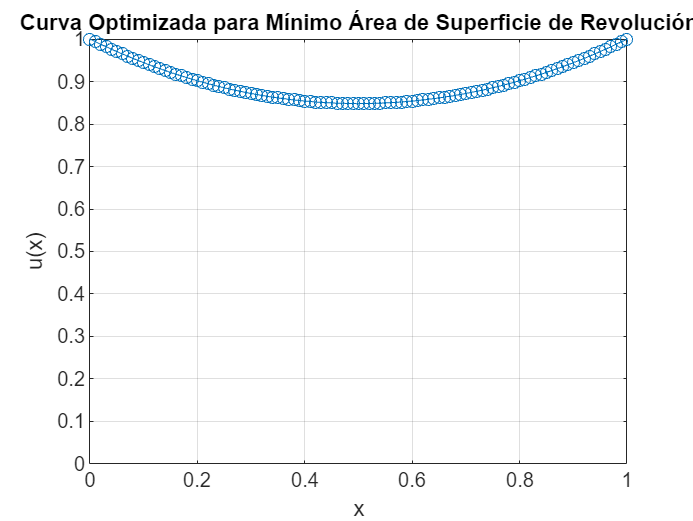

% fprintf('Curva optimizada u(x):\n');
% disp(u);


% Graficar la curva optimizada
figure;
plot(x, u, '-o');
xlabel('x'); ylabel('u(x)');
ylim([0,1])
title('Curva Optimizada para Mínimo Área de Superficie de Revolución');
grid on;



% Cálculo del área
area_total = area_func(u, n);

% Mostrar el área
fprintf('El área total (fórmula) es: %.6f\n', area_total);

El área total (fórmula) es: 0.954092



% Cálculo aproximado del área usando promedio entre puntos consecutivos
area_total = 0;
for j = 1:n
    area_total = area_total + (u(j) + u(j+1)) / (2 * n);
end

% Mostrar el área total
fprintf('El área aproximada (promedio entre puntos) es: %.6f\n', area_total);

El área aproximada (promedio entre puntos) es: 0.898206


## Construir superficie de revolución

% % Construir superficie de revolución
% sup = construccion_puntos(puntos);
% 
% % Representar superficie de revolución
% plot(sup) % Aquí hacer representación 3D
% 
% function sup = construccion_puntos(puntos)
%     f = puntos'; % Aquí hay que construir una función con la interpolación adecuada
%     sup = 2*pi*f;
% end




### Anexo

% Función para calcular el gradiente en cada punto
function grad = calculo_gradiente(u, n)
    grad = zeros(size(u)); % Inicializar el gradiente

    % Para k = 0
    delta_next = u(2) - u(1);
    inc_next = u(1) + u(2);
    grad(1) = (1 / (2 * n)) * ( ...
        sqrt(1 + n^2 * delta_next^2) - ...
        n^2 * delta_next * inc_next / sqrt(1 + n^2 * delta_next^2) ...
    );

    % Para k = 1, ..., n-1
    for k = 2:n
        delta_prev = u(k) - u(k-1);
        delta_next = u(k+1) - u(k);
        inc_prev = u(k-1) + u(k);
        inc_next = u(k) + u(k+1);

        grad(k) = (1 / (2 * n)) * ( ...
            n^2 * delta_prev * inc_prev / sqrt(1 + n^2 * delta_prev^2) + ...
            sqrt(1 + n^2 * delta_prev^2) + ...
            sqrt(1 + n^2 * delta_next^2) - ...
            n^2 * delta_next * inc_next / sqrt(1 + n^2 * delta_next^2) ...
        );
    end

    % Para k = n
    delta_prev = u(n+1) - u(n);
    inc_prev = u(n) + u(n+1);
    grad(n+1) = (1 / (2 * n)) * ( ...
        n^2 * delta_prev * inc_prev / sqrt(1 + n^2 * delta_prev^2) + ...
        sqrt(1 + n^2 * delta_prev^2) ...
    );
end


function area = area_func(u, n)
    % Cálculo del área total (fórmula completa)
    area = 0;
    for j = 1:n
        delta_u = u(j+1) - u(j); % Diferencia entre u_{j+1} y u_j
        factor = sqrt(1 + n^2 * delta_u^2); % Factor raíz
        Tj = ((u(j) + u(j+1)) * factor) / (2 * n); % Término de área
        area = area + Tj; % Sumar al área total
    end
end


function alpha_opt = busqueda_dicotomica(u, grad, n)
    % Parámetros de la búsqueda
    a = 0; % Límite inferior
    b = 1; % Límite superior
    tol = 1e-5; % Tolerancia
    epsilon = tol / 10; % Desplazamiento pequeño para evaluar
    
    while (b - a) > tol

        x = (a + b) / 2;

        % Dividir el intervalo
        alpha1 = x - epsilon/2;
        alpha2 = x + epsilon/2;
        
        % Evaluar la función objetivo en alpha1 y alpha2
        f1 = area_func(u - alpha1 * grad, n);
        f2 = area_func(u - alpha2 * grad, n);
        
        % Reducir el intervalo basado en las evaluaciones
        if f1 < f2
            b = alpha2; % Mover límite superior
        else
            a = alpha1; % Mover límite inferior
        end
    end
    
    % Devuelve el punto medio del intervalo como alpha óptimo
    alpha_opt = (a + b) / 2;
end